## **Proudění plynů a par - CHOVÁNÍ LAVALOVY DÝZY**

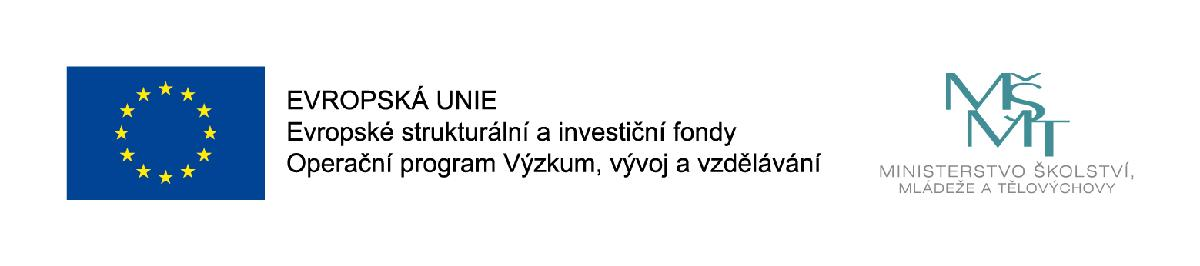

#### prof. Ing. Josef ŠTĚTINA, Ph.D. / Vysoké učení technické v Brně

#### email: [josef.stetina@vutbr.cz](mailto:josef.stetina@vutbr.cz)

#### www: [http://termomechanika.online/](http://termomechanika.online/)

Vliv různých vstupních podmínek - různých vstupních rychlostí

Rovnice kontinuity    $$\frac{{Sw}}{v} = konst.\quad  \Rightarrow \quad \frac{{dS}}{S} = \frac{{dv}}{v} - \frac{{dw}}{w}$$

Rovnice adiabaty    $$p{v^\kappa } = konst.\quad  \Rightarrow \quad \frac{{dp}}{p} + \kappa \frac{{dv}}{v} = 0$$

Rovnice pohybová    $$ - vdp = d\left( {\frac{{{w^2}}}{2}} \right) = wdw\quad  \Rightarrow \quad  - \frac{{dw}}{w} = \frac{{vdp}}{{{w^2}}}$$

Po dosazení do rovnice kontinuity


$$$\frac{{dS}}{S} = \left( {\frac{{ - 1}}{{\kappa p}} + \frac{v}{{{w^2}}}} \right)dp = \frac{{\kappa pv - {w^2}}}{{\kappa {w^2}}}\frac{{dp}}{p} = \frac{{{a^2} - {w^2}}}{{\kappa {w^2}}}\frac{{dp}}{p} = \frac{{1 - M{a^2}}}{{\kappa M{a^2}}}\frac{{dp}}{p}$$$


Závěr pro fyzikální úvahy


$$$\frac{{dS}}{S} = \frac{{1 - M{a^2}}}{{\kappa M{a^2}}}\frac{{dp}}{p}$$$
            
$$$ - \frac{{dw}}{w} = \frac{{vdp}}{{{w^2}}}$$$


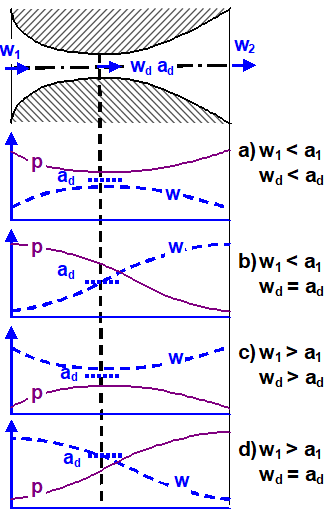

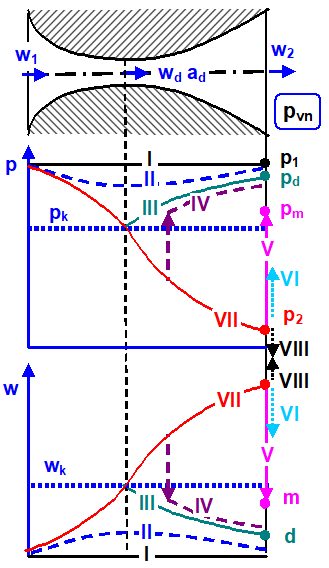

**LAVALOVA DÝZA **při různém protitlaku ***p******vn***

***I.***  ***p******1******= ******p******vn***

**Varianta ****I***:*   ***p******vn*** ***= p******1*** K disposici je nulový tlakový spád, rychlost výtoku z dýzy  je nulová (*w**2**=0*), proto hmotnostní tok je rovněž nulový.  

**Varianta ****II****:**  Tlak je všude vyšší než tlak kritický, v konvergentní části  tlak z *p**1* pozvolna klesá, v hrdle je nejmenší, nikoli však kritický, v divergentní části opět pozvolna stoupá až na konečný tlak *p**1*. Tomu odpovídá v konvergentní části pomalý nárůst rychlosti ( která je v hrdle největší, nikoli však kritická),  v divergentní  pak pomalý pokles rychlosti na hodnotu nenulovo. V zúžení tedy probíhá podzvuková expanze (tryska), v rozšíření podzvuková komprese (difusor). Hmotnostní tok při podkritickérychlosti nedosáhne maximální hodnoty.

**Varianta ****III****:**Pro Lavalovu dýzu daných rozměrů a tvaru existuje zcela určitý protitlak *p**C*, při kterém  v zúžení tlak klesne až na tlak kritický do bodu K (křivka poklesu se kryje s křivkou *f* při standardní činnosti Lavalovydýzy). Až do bodu K probíhá standardní podzvuková expanze. Při vstupu proudu do rozšíření však dojde k náhlému přechodu z podzvukové expanze na podzvukovou kompresi, takže tlak okamžitě začne narůstat (křivka *c*) až na hodnotu *p**C*. V bodě K se skokem změní směrnice tečny ke křivce *f *(ležící ve 2. kvadrantu) na směrnici tečny ke křivce *c *(ležící v 1. kvadrantu). Tomu odpovídá křivka rychlosti proudu, která až do bodu K kopíruje křivku *f*nárůstem až na rychlost kritickou (zvuku). V bodě K však dojde k náhlému poklesu rychlosti, který je podle křivky*c*trvalý až na podkritickouhodnotu  *w**C*. Hmotnostní tok v hrdle i ve výstupním průřezu dosáhne mezní  hodnoty (pro danou dýzu je to maximálně možný hmotnostní tok), která zůstává konstantní i při dalším snižování protitlaku pod hodnotu *p**C**.*  

clear;

S = linspace(0.0019,0.0056,100)

S =     0.0019    0.0019    0.0020    0.0020    0.0020    0.0021    0.0021    0.0022    0.0022    0.0022    0.0023    0.0023    0.0023    0.0024    0.0024    0.0025    0.0025    0.0025    0.0026    0.0026    0.0026    0.0027    0.0027    0.0028    0.0028    0.0028    0.0029    0.0029    0.0029    0.0030    0.0030    0.0031    0.0031    0.0031    0.0032    0.0032    0.0032    0.0033    0.0033    0.0034    0.0034    0.0034    0.0035    0.0035    0.0035    0.0036    0.0036    0.0037    0.0037    0.0037


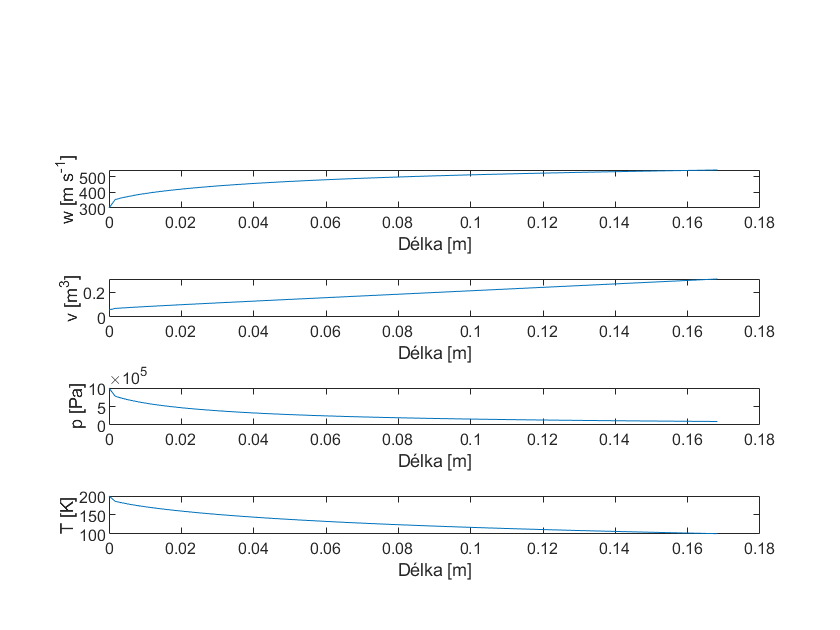

x = linspace(0,0.1682,100);

S_size=length(S);
w=zeros(S_size,1);
T=zeros(S_size,1);
p=zeros(S_size,1);
v=zeros(S_size,1);

kappa = 1.41;
r = 287;

m = 10;
w(1)= 299.6;
T(1)=200;
p(1)=1e6;
v(1)= 287*T(1)/p(1);

%numericke reseni diferencialni rovnice
for ii=1:(S_size-1)
    w(ii+1)=-(S(ii+1)-S(ii))/(S(ii))*w(ii)*1/(1-w(ii)^2/(kappa*r*T(ii)))+w(ii);
    v(ii+1)=(S(ii+1)*w(ii+1))/(m);
    p(ii+1)=p(ii)*(v(ii)/v(ii+1))^kappa;
    T(ii+1)=p(ii+1)*v(ii+1)/r;
end

subplot(5,1,2)
plot(x,w)
xlabel('Délka [m]')
ylabel('w [m s^{-1}]')

subplot(5,1,3)
plot(x,v)
xlabel('Délka [m]')
ylabel('v [m^{3}]')

subplot(5,1,4)
plot(x,p)
xlabel('Délka [m]')
ylabel('p [Pa]')

subplot(5,1,5)
plot(x,T)
xlabel('Délka [m]')
ylabel('T [K]')